## **Stacker crane**

#### *Horizontal movement*

%Dates:
vh_max= 2;% [m/s] velocità massima orizzontale
ah= 0.4;% [m/s^2] accelerazione/decelerazione massima orizzontale

Sh1=15;% O-P1 [m]
Sh2=15;% P1-P2 [m]
Sh3=-30;% P2-O[m]


mlc = CreateLdmComp(6)

mlc = struct with fields:
    vldm: {6×1 cell}
    name: 'ldm composta'
    time: [1×1 struct]
    disp: [1×1 struct]



mlc.disp.um = 'm'; %unit of measure

%first ML
mlc.vldm{1}.file = 'ConstSym';
mlc.vldm{1}.par.xv = 2/5;
mlc.vldm{1}.name = 'O-P1';
mlc.vldm{1}.h = Sh1; %stroke
mlc.vldm{1}.ta = 12.5; %drive time [s]

%second ML
mlc.vldm{2}.file = 'Stop';
mlc.vldm{2}.name = 'unload';
mlc.vldm{2}.h = 0; %no movement
mlc.vldm{2}.ta = 10; % drive time [s]

%third ML
mlc.vldm{3}.file = 'ConstSym';
mlc.vldm{3}.par.xv = 2/5;
mlc.vldm{3}.name = 'P1-P2';
mlc.vldm{3}.h = Sh2; %negative for caming back
mlc.vldm{3}.ta = 12.5; %[s]

%fourth ML
mlc.vldm{4}.file = 'Stop';
mlc.vldm{4}.name = 'load';
mlc.vldm{4}.h = 0; %negative for caming back
mlc.vldm{4}.ta = 10; %[s]

%fifth ML
mlc.vldm{5}.file = 'ConstSym';
mlc.vldm{5}.par.xv = 1/4;
mlc.vldm{5}.name = 'P2-O';
mlc.vldm{5}.h = Sh3; %negative for caming back
mlc.vldm{5}.ta = 20; %[s]

%sixth ML
mlc.vldm{6}.file = 'Stop';
mlc.vldm{6}.name = 'base station';
mlc.vldm{6}.h = 0; %negative for caming back
mlc.vldm{6}.ta = 10; %[s]

mlc = EvalLdmComp(mlc,1000)

mlc = struct with fields:
    vldm: {6×1 cell}
    name: 'ldm composta'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


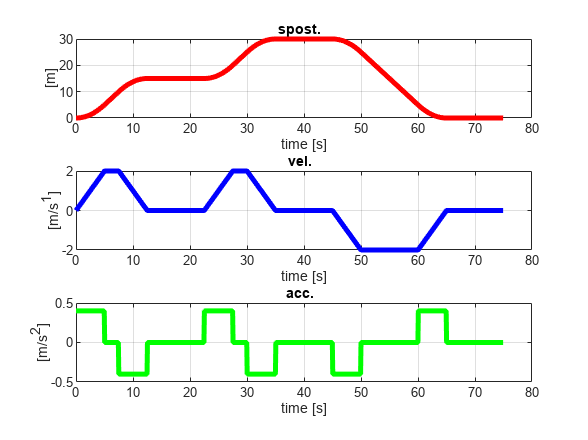

PlotLdmComp(mlc);


% rinomino le variabili in gioco 
x = mlc.moto.data{1}.v;
xp = mlc.moto.data{2}.v;
xpp = mlc.moto.data{3}.v;
t = mlc.moto.time;

### Vertical movement

%Dates:
vh_max= 1;% [m/s] velocità massima verticale
ah= 0.4;% [m/s^2] accelerazione/decelerazione massima verticale

Sv1=10;% O-P1 [m]
Sv2=-5;% P1-P2 [m]
Sv3=-5;% P2-O[m]


mlc = CreateLdmComp(6)

mlc = struct with fields:
    vldm: {6×1 cell}
    name: 'ldm composta'
    time: [1×1 struct]
    disp: [1×1 struct]



mlc.disp.um = 'm'; %unit of measure

%first ML
mlc.vldm{1}.file = 'ConstSym';
mlc.vldm{1}.par.xv = 1/5;
mlc.vldm{1}.name = 'O-P1';
mlc.vldm{1}.h = Sv1; %stroke
mlc.vldm{1}.ta = 12.5; %drive time [s]

%second ML
mlc.vldm{2}.file = 'Stop';
mlc.vldm{2}.name = 'unload';
mlc.vldm{2}.h = 0; %no movement
mlc.vldm{2}.ta = 10; % drive time [s]

%third ML
mlc.vldm{3}.file = 'ConstSym';
mlc.vldm{3}.par.xv = 1/3;
mlc.vldm{3}.name = 'P1-P2';
mlc.vldm{3}.h = Sv2; %negative for caming back
mlc.vldm{3}.ta = 12.5; %[s] 
% se fosse andato a velocità e accelerazione
% avrebbe impiegato solo 7.5 s non seguendo più lo spostamento orizzontale

%fourth ML
mlc.vldm{4}.file = 'Stop';
mlc.vldm{4}.name = 'load';
mlc.vldm{4}.h = 0; %negative for caming back
mlc.vldm{4}.ta = 10; %[s]

%fifth ML
mlc.vldm{5}.file = 'ConstSym';
mlc.vldm{5}.par.xv = 1/3;
mlc.vldm{5}.name = 'P2-O';
mlc.vldm{5}.h = Sv3; %negative for caming back
mlc.vldm{5}.ta = 20; %[s]
%se fosse andato a velocità e accelerazione
% avrebbe impiegato solo 7.5 s non seguendo più lo spostamento orizzontale

%sixth ML
mlc.vldm{6}.file = 'Stop';
mlc.vldm{6}.name = 'base station';
mlc.vldm{6}.h = 0; %negative for caming back
mlc.vldm{6}.ta = 10; %[s]

mlc = EvalLdmComp(mlc,1000)

mlc = struct with fields:
    vldm: {6×1 cell}
    name: 'ldm composta'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


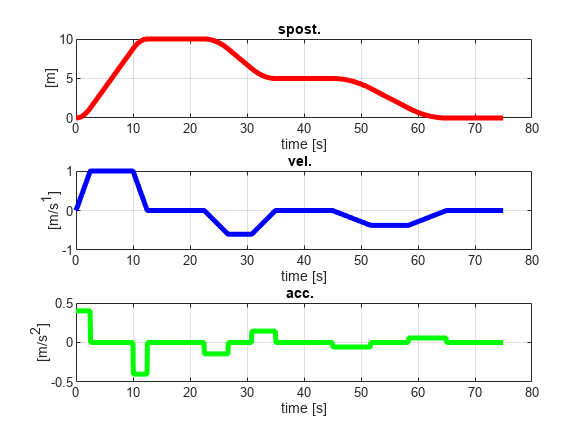

PlotLdmComp(mlc);


% rinomino le variabili in gioco 
y = mlc.moto.data{1}.v;
yp = mlc.moto.data{2}.v;
ypp = mlc.moto.data{3}.v;
t = mlc.moto.time;

# (HORIZONTAL) Adattamento dinamico movimento 

#### DATI CARICO:

D= 0.32; %[m] diametro della ruota
R= D/2;
fv= 0.009; %coefficiente attrito volvente
P0= 8000; %[N] peso carrello orizzontale vuoto
Pcv= 3000; %[N] peso del carrello verticale vuoto
P= 8000; %[N] peso massimo trasportabile
g= 9.81;


#### Calcolo $\omega$  e $\dot{\omega}$ 

wc=xp/R; %rad/s
wpc=xpp/R; %rad/s^2
wc_max=max(abs(wc)) %rad/s

wc_max = 12.5000

wc_rms=rms(wc)

wc_rms = 7.2169

wpc_max=max(abs(wpc)) %rad/s^2

wpc_max = 2.5000

wpc_rms=rms(wpc) %rad/s^2

wpc_rms = 1.5819

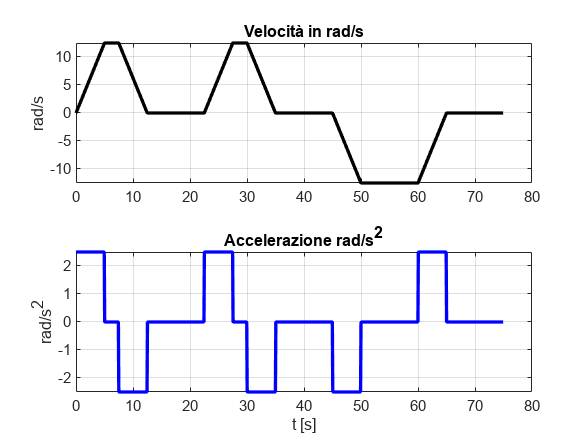


figure('color','white');
subplot(2,1,1);
 plot(t,wc,'k','linewidth',2);  grid on;
  title('Velocità in rad/s');
ylabel('rad/s')
subplot(2,1,2);
 plot(t,wpc,'b','linewidth',2);  grid on;
  title('Accelerazione rad/s^2');
  ylabel('rad/s^2')
xlabel('t [s]')

#### Coppia e Potenza carico

for k=1:length(t)
    if(t(k)<12.5)
    
    Ca(k)=(P+P0+Pcv)*fv*R*sign(wc(k));
    Ci(k)=wpc(k)*(((P+P0+Pcv)/g)*R^2);

    end
    if (t(k)>12.5)&&(t(k)<35)
    
    Ca(k)=(P0+Pcv)*fv*R*sign(wc(k));
    Ci(k)=wpc(k)*(((P0+Pcv)/g)*R^2);
    end
    if (t(k)>35)
    
    Ca(k)=(P+P0+Pcv)*fv*R*sign(wc(k));
    Ci(k)=wpc(k)*(((P+P0+Pcv)/g)*R^2);
    
    end
end

Cu=(Ca+Ci);
Cu_rms=rms(Cu);

Wc=Cu.*wc;
Wc_rms=rms(Wc);

Lc=mean(Cu.*wpc);

### Grafici coppie e potenza del carico

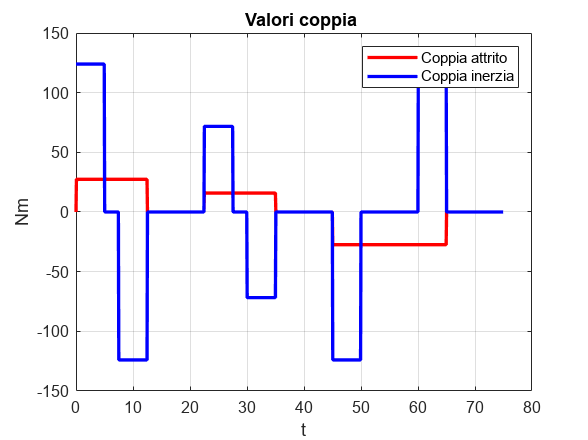

figure('color','white');
plot(t, Ca,'r',t,Ci,'b','linewidth',2); grid on;
title('Valori coppia ');
xlabel('t');
ylabel('Nm')
grid on;
legend('Coppia attrito ','Coppia inerzia')

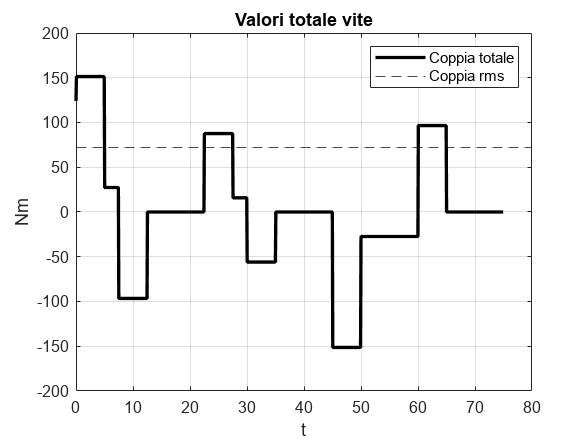


figure('color','white');
plot(t,Cu,'k','linewidth',2); 
hold on;grid on;
yline(Cu_rms,'k--')
xlabel('t');
ylabel('Nm')
legend('Coppia totale','Coppia rms')
title('Valori totale vite');

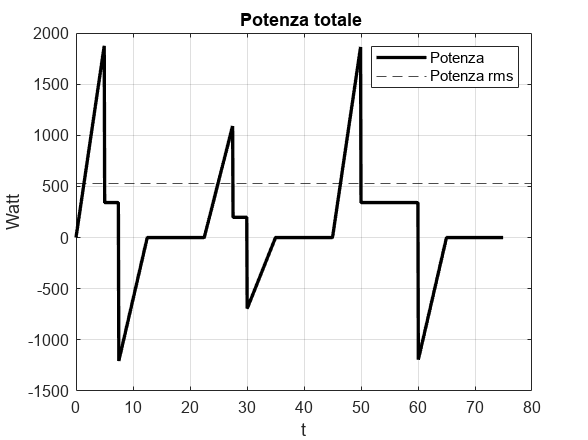


figure('color','white');
plot(t,Wc,'k','linewidth',2); 
hold on;grid on;
yline(Wc_rms,'k--')
xlabel('t');
ylabel('Watt')
legend('Potenza','Potenza rms')
title('Potenza totale ');


Cu_max=max(abs(Cu))

Cu_max = 151.3151

Wc_max=max(abs(Wc))

Wc_max = 1.8744e+03

Wc_rms=rms(Wc)

Wc_rms = 529.5692

#### Dati per la scelta  inseriti nella  struttura Load

Load.Cu_rms=Cu_rms;    %coppia RMS 
Load.Cu_max=Cu_max;    %coppia massima 
Load.Lc =Lc;           %media del prodotto Cu*wc 
Load.wpc_rms=wpc_rms;    %accelerazione RMS 
Load.wpc_max=wpc_max;    %accelerazione massima
Load.wc_max=wc_max;      %veloctà massima 
disp(Load);

     Cu_rms: 71.6994
     Cu_max: 151.3151
         Lc: 106.5091
    wpc_rms: 1.5819
    wpc_max: 2.5000
     wc_max: 12.5000



### Scelta Motore 

Famiglia di trasmissioni scelta: ESP 100/2

% Velocità massima della trasmissione
nTMax=3000    

nTMax = 3000

Valore PcOT_rms = 439.8649
Valore KcOT_rms = 7081.8722
Valore PcOT_max = 969.5939
Valore KcOT_max = 9457.1967
Valore FcOTT = 20.973
Valore EcOTT = 84.1539
Valore FcOT_max = 31.1383
Valore EcOT_max = 97.2481
Tabella motori e rapporti di trasmissione
       Codice        CN        Jm       nMAX    Tmax    nMAX1    Pm_rms    Km_rms      Pm_max      Km_max    Fm_rms    Em_rms    Fm_max    Em_max     IOTT      Imin      Imax 
    ____________    ____    ________    ____    ____    _____    ______    ______    __________    ______    

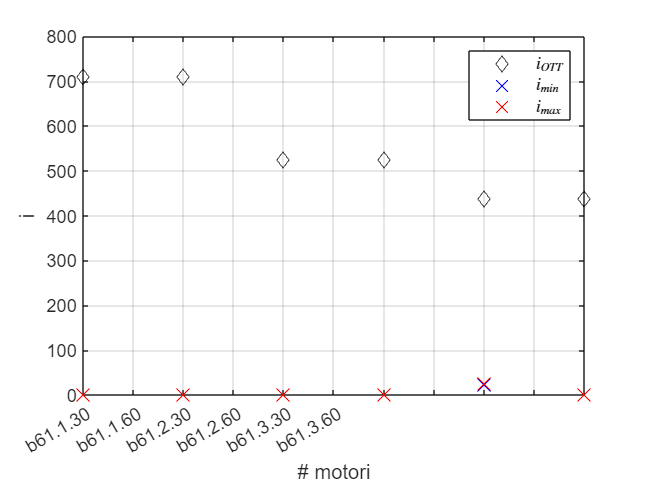

Valore Pcarico_rms = 38192.5229
Valore Kcarico_rms = 21.1497
Valore Fcarico_rms = 195.4291
Valore Ecarico_rms = 4.5989
Valore Pcarico_max = 126881.6664
Valore Kcarico_max = 28.2436
Valore Fcarico_max = 356.2045
Valore Ecarico_max = 5.3145


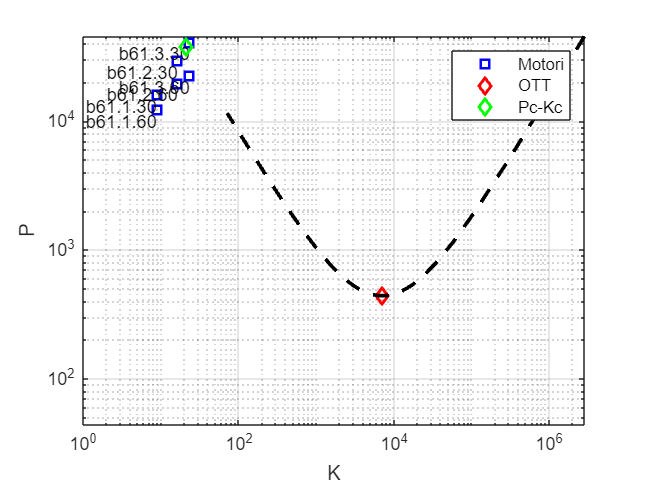

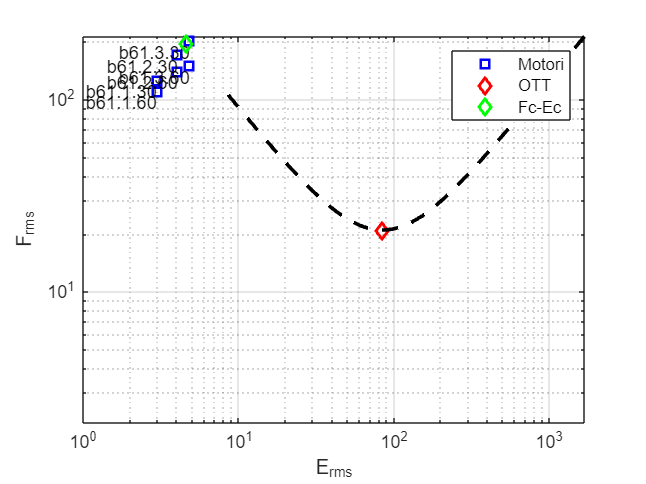

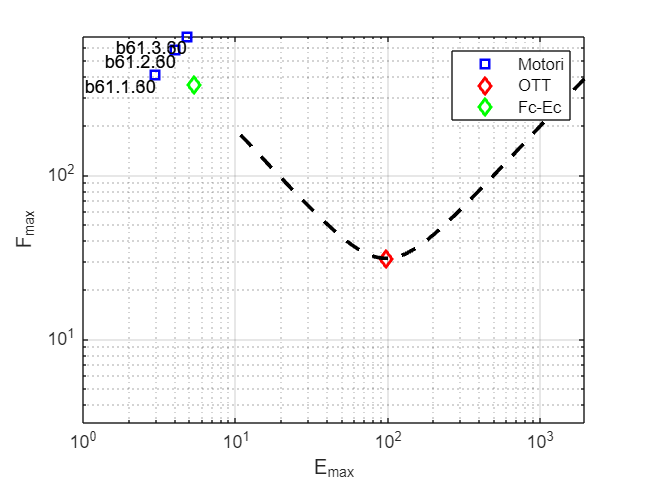

mot = AdattamentoDinamico(@DB_Mot, Load, nTMax);

Dai dati si decide:

m=5; %motore scelto per la verifica

[mot]=DB_Mot();

Tmax=mot(m).Tmax;
CN=mot(m).CN;
Jm=mot(m).Jm;
nMAX=min(nTMax,mot(m).nMAX);
wMAX=nMAX*2*pi/60;

disp('Tabella motore scelto');

Tabella motore scelto


Tablemot = struct2table(mot(m));  %solo per visualizzazione
disp(Tablemot);

     Codice     CN        Jm       nMAX    Tmax
    ________    ___    ________    ____    ____

    b61.3.30    3.1    0.000235    3000    10.8



### Verifica

Con il  motore/riduttore scelto  si  calcola la coppia e la potenza erogata dal motore.    

Si  verifica che  $C_{rms}<C_N$ e si calcola il margine di coppia $M_C=\frac{C_N}{C_{rms}}$

Si rappresenta  il ciclo  di carico verificando che sia all'interno del campo intermittente

**Verifica**

%rendimento,inerzia,rapporto T
T.Codice='ESP 100/2';
T.eta=1;%caso ideale
T.i=20;%rapporto di riduzione
T.JT=2.8e-5; %momento inerzia kgm^2 lato motore
T.M2=250; %Nm coppia massima all'uscita

disp('Tabella riduttore scelto');

Tabella riduttore scelto


Tablemot = struct2table(T);  %solo per visualizzazione
disp(Tablemot);

     Codice      eta    i       JT       M2 
    _________    ___    __    _______    ___

    ESP 100/2     1     20    2.8e-05    250




Cm_v=(Cu/(T.eta*T.i))+wpc*T.i*(Jm+T.JT); %coppia motore di verifica
Cm_vrms=rms(Cm_v);
Wm_v=Cm_v.*wc*T.i;
Cm_vmax=max(abs(Cm_v));
MC=CN/Cm_vrms; %determinare margine di coppia

nc=wc*60/(2*pi);
n_mot=T.i*nc;

disp(['Valore di verifica RMS Cm_v = ', num2str(Cm_vrms)] );

Valore di verifica RMS Cm_v = 3.5928


disp(['Valore di verifica MAX Cm_v = ', num2str(Cm_vmax)] );

Valore di verifica MAX Cm_v = 7.5789


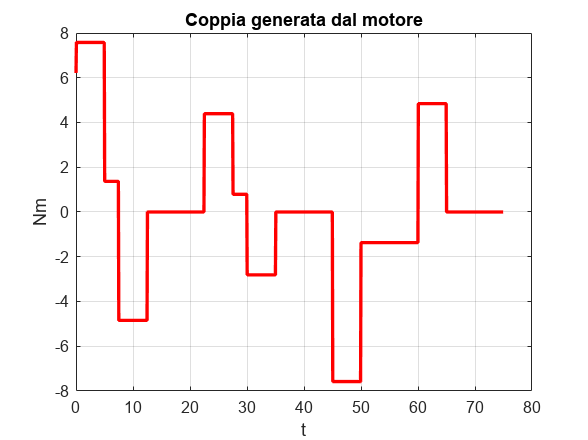


%andamento coppia e potenza
figure('color','white');
plot(t,Cm_v,'r','linewidth',2); 
hold on;grid on;
xlabel('t');
ylabel('Nm')
title('Coppia generata dal motore');

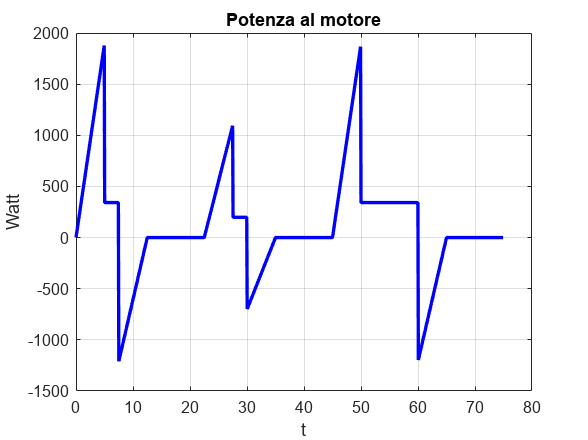


figure('color','white');
plot(t,Wm_v,'b','linewidth',2); 
hold on;grid on;
xlabel('t');
ylabel('Watt')
title('Potenza al motore');

**Verifica termica**

if(MC>1) disp(['Verifica termina soddisfatta, MC = ', num2str(MC), ' > 1'] );
    else disp(['Verifica termica non soddisfatta,  MC = ', num2str(MC), ' < 1'] );
end

Verifica termica non soddisfatta,  MC = 0.86284 < 1


**Verifica "picco di coppia" (ciclo di carico)**

Disegno le regioni S1 e Si (approssimazioni a rettangolo)

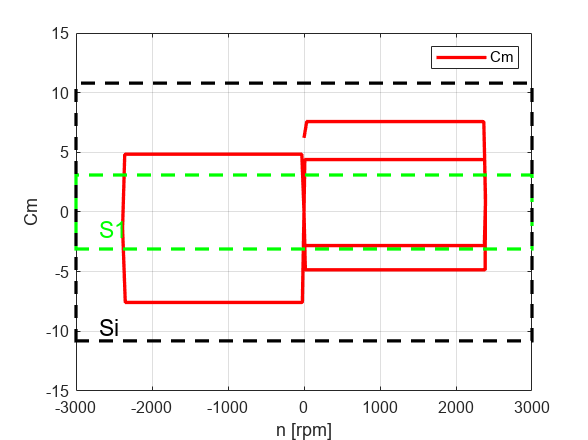

figure
plot(n_mot,Cm_v,'r','linewidth',2 )
rectangle('Position',[-nMAX -CN 2*nMAX 2*CN],'EdgeColor', 'g','LineStyle','--','linewidth',2) 
rectangle('Position',[-nMAX -Tmax 2*nMAX 2*Tmax],'EdgeColor','k','LineStyle','--','linewidth',2) 
grid on;
text(-nMAX+nMAX/10,-CN+CN/2,'S1','Color','g','FontSize',14)
text(-nMAX+nMAX/10,-Tmax+Tmax/10,'Si','Color','k','FontSize',14)

xlabel('n [rpm]')
ylabel('Cm')
legend('Cm')

# (VERTICAL) Adattamento dinamico movimento 

# -NO COUNTERWEIGHT

#### DATI CARICO:

Dt= 0.2;% diametro tamburo
Dv= 0.182; %[m] diametro delle ruote del carrello (per attrivo volvente)
R= Dt/2;% raggio del tamburo che muove la fune
fv= 0.009; %coefficiente attrito volvente
Pcv= 3000; %[N] peso carrello vuoto
%Pct= 7000;% peso dello contropeso
P= 8000; %[N] peso massimo trasportabile
g= 9.81;


#### Calcolo $\omega$  e $\dot{\omega}$ 

wc=yp/R; %rad/s
wpc=ypp/R; %rad/s^2
wc_max=max(abs(wc)) %rad/s

wc_max = 10

wc_rms=rms(wc)

wc_rms = 4.1999

wpc_max=max(abs(wpc)) %rad/s^2

wpc_max = 4.0000

wpc_rms=rms(wpc) %rad/s^2

wpc_rms = 1.1670

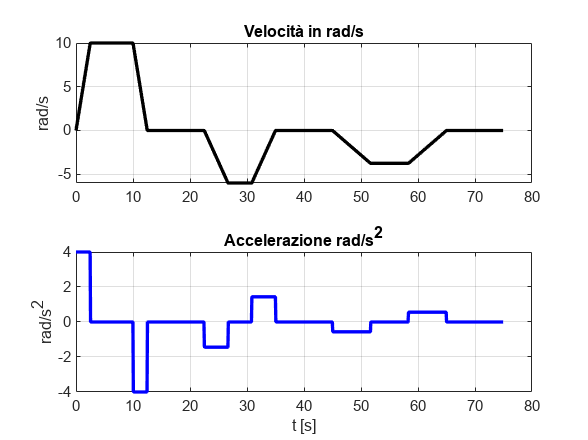


figure('color','white');
subplot(2,1,1);
 plot(t,wc,'k','linewidth',2);  grid on;
  title('Velocità in rad/s');
ylabel('rad/s')
subplot(2,1,2);
 plot(t,wpc,'b','linewidth',2);  grid on;
  title('Accelerazione rad/s^2');
  ylabel('rad/s^2')
xlabel('t [s]')

#### Coppia e Potenza carico

for k=1:length(t)
    if(t(k)<12.5)
    
    Cf(k)=(m+mc)*g*tauv/etav;
    Ca(k)=(P+P0)*fv*R*sign(wc(k));% attrito volvente
    Ci(k)=wpc(k)*(((P+P0)/g)*R^2); %inerzia

    end
    if (t(k)>12.5)&&(t(k)<35)
    
    Cf(k)=(m+mc)*g*tauv/etav;
    Ca(k)=(P0)*fv*R*sign(wc(k));
    Ci(k)=wpc(k)*(((P0)/g)*R^2);
    end
    if (t(k)>35)
    
    Cf(k)=(m+mc)*g*tauv/etav;
    Ca(k)=(P+P0)*fv*R*sign(wc(k));
    Ci(k)=wpc(k)*(((P+P0)/g)*R^2);
    
    end
end

Unrecognized function or variable 'mc'.


Cu=(Cf+Ca+Ci);%coppia totaleg
Cu_rms=rms(Cu);

Wc=Cu.*wc;
Wc_rms=rms(Wc);

Lc=mean(Cu.*wpc);